# 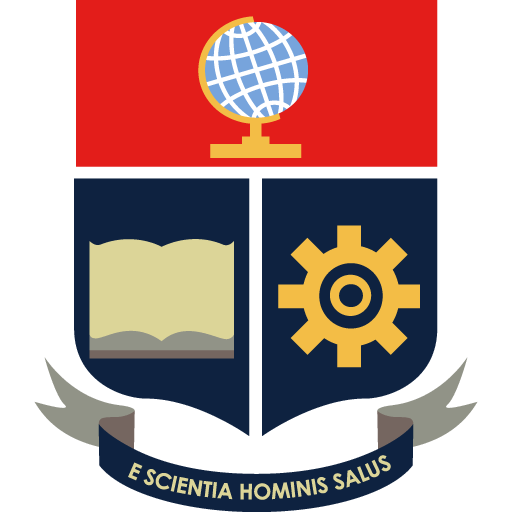Escuela Politécnica Nacional

#### `UTILIZACIÓN DEL SISTEMA DE RECONOCIMIENTO DE GESTOS EMPLEADO EN EL PROYECTO DE INVESTIGACIÓN PIGR-19-07 PARA EL COMANDO DE UN SISTEMA MULTI-AGENTE`

# **Comando del Sistema Multi-Agente**

## `Control de los agentes robóticos`

#### En base a:

**Modo 1: **Seguimiento de 3 agentes a un Lider Virtual

**Modo 2: **Seguimiento de 2 agentes a un agente Lider Seguido

                  *Modo 1*                                *Modo 2*

      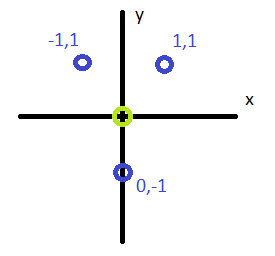   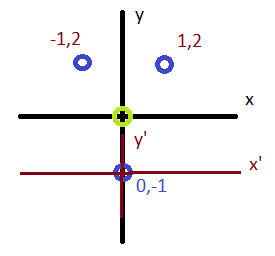

    mod=1;
if mod==1
    mssg="Modo 1 seleccionado";
    a=3;
    fprintf("|/| Modo 1")
elseif mod==2
    mssg="Modo 2 seleccionado";
    a=4;
    fprintf("Modo 2 |/|")
else
    a=1;
    mssg="Seleccionar modo";
end

|/| Modo 1

 "Modo 1 seleccionado";
  
% if mod==1     
% %     waypoint1=[PosX1(length(PosX1)) PosY1(length(PosY1));x+rx1 y+ry1];
% %     waypoint2=[PosX2(length(PosX2)) PosY2(length(PosY2));x+rx2 y+ry2];
% %     waypoint3=[PosX3(length(PosX3)) PosY3(length(PosY3));x+rx3 y+ry3];
% elseif mod==2
%     %en este caso a las posiciones rxi,ryi se les resta aquellas del agente
%     % seguidor para que este se vuelva su referencia, siendo este el robot 2
%     
% %     waypoint1=[PosX1(length(PosX1)) PosY1(length(PosY1));PosX2(length(PosX2))+rx1-rx2 PosY2(length(PosY2))+ry1-ry2];
% %     waypoint2=[PosX2(length(PosX2)) PosY2(length(PosY2));x+rx2 y+ry2];
% %     waypoint3=[PosX3(length(PosX3)) PosY3(length(PosY3));PosX2(length(PosX2))+rx3-rx2 PosY2(length(PosY2))+ry3-ry2];
% end

if server.NumBytesAvailable~=0
data=read(server,server.NumBytesAvailable,"uint8");
option=data(length(data));
write(client2,option,"uint8");
end

## `Selección de Acción por Referencia (sin HGR)`

- `Ejecutar en la otra Instancia de MATLAB el archivo para ingreso de comandos de referencia (.mxl)`

## `Selección de Acción con el HGR`

- `Ejecutar en la otra Instancia de MATLAB el archivo del Sistema de Reconocimiento de Gestos (.m)`

if server.NumBytesAvailable~=0
data=read(server,server.NumBytesAvailable,"uint8");
option=data(length(data));
end

while option~=3&&option~=4
if server.NumBytesAvailable~=0
data=read(server,server.NumBytesAvailable,"uint8");
option=data(length(data));
end

if option==1%WaveOut
    niv=2;
    nivel="Movimiento de trayectoria grupal";%32s
elseif option==2%WaveIn
    niv=1;
    nivel="Control de formación            ";
end

printStatus(nivel,ind)
ind=2;
end

Nivel seleccionado:
            Control de formación

 

if option==3%Fist
    if niv==1
        open("menu_op1_multiple.mlx")
    elseif niv==2
        open("menu_op2.mlx")
    end
end


function printStatus (mssg,ind)
     if ind == 1
        % The very first time we don't need to delete the old text
        fprintf('Nivel seleccionado:\n')
        fprintf('%32s', mssg);
     else
        % Each \b removes one character from the previous fprintf.
        fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b')
        fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bNivel seleccionado:\n')
%         fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b%32s', mssg);
        fprintf('%32s', mssg);
     end
end